% KaplanDeriaz3D - Hydro Turbine Blade Designer with CAD/Excel Export
% Copyright (C) 2026 Juan Fernandez Lozano
%
% This program is free software: you can redistribute it and/or modify
% it under the terms of the GNU General Public License as published by
% the Free Software Foundation, either version 3 of the License, or
% (at your option) any later version.
%
% This program is distributed in the hope that it will be useful,
% but WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the
% GNU General Public License for more details.
%
% You should have received a copy of the GNU General Public License
% along with this program. If not, see <https://www.gnu.org/licenses/>.

% =========================================================================
% SCRIPT DE MATLAB: DISEÑO 3D DE ÁLABE KAPLAN AXIAL Y RODETE COMPLETO (TFM)
% ROTACIÓN DEL RODETE: ANTIHORARIA (Visto desde arriba)
%
% Este código resuelve de forma numérica la ecuación diferencial del 
% alabeado detallada en la memoria, incorporando las eficiencias
% hidrodinámicas, el cálculo exacto de la cuerda 3D, la solidez requerida
% y el renderizado 3D del rodete.
% =========================================================================
clear; clc; close all;

%% ========================================================================
% BLOQUE 1: PARÁMETROS ENERGÉTICOS, GEOMÉTRICOS Y EFICIENCIAS
% Se definen las condiciones nominales de la instalación hidroeléctrica,
% así como los rendimientos característicos de la máquina.
% =========================================================================
RPM = 450;                % Velocidad de rotación del rodete (rpm)
Q0 = 12;                  % Caudal volumétrico nominal extraído del salto (m^3/s)
Hn = 15;                  % Altura neta disponible en la instalación (m)
g = 9.81;                 % Aceleración de la gravedad (m/s^2)
rho = 1000;               % densidad del agua (1000kg/m^3)

% Rendimientos de la turbomáquina (Eficiencias internas)
eta_h = 0.90;             % Eficiencia hidráulica (pérdidas por fricción y disipación)
eta_v = 0.96;             % Eficiencia volumétrica (pérdidas por fugas en el juego del cubo)
eta_o = 0.98;             % Eficiencia orgánica/mecánica (pérdidas por rozamiento en cojinetes)
eta_t = eta_h * eta_v * eta_o; % Rendimiento total de la turbina

% Dimensiones geométricas principales del canal de paso
R_cubo = 0.3;             % Radio interno del rodete (m)
R_punta = 0.65;           % Radio externo del rodete (m)
L_z = 0.35;               % Longitud axial del álabe (m)

R_m = sqrt((R_punta^2 + R_cubo^2) / 2); % Radio medio hidráulico (m)

%% ========================================================================
% BLOQUE 2: CINEMÁTICA DEL FLUIDO Y VELOCIDADES EFECTIVAS
% Se aplican las correcciones por eficiencias sobre el caudal y las alturas
% =========================================================================
omega = (2 * pi * RPM) / 60;              % Velocidad angular de rotación (rad/s)
Q_real = Q0 * eta_v;                      % Caudal útil que atraviesa efectivamente el rodete (m^3/s)
Area_paso = pi * (R_punta^2 - R_cubo^2);  % Área de la sección transversal de flujo (m^2)
V_z = Q_real / Area_paso;                 % Velocidad meridional/axial constante (Vm1 = Vm2 = V_z)

% Potencias teóricas y útiles del salto
W_n = rho * g * Q0 * Hn;                 % Potencia hidráulica bruta disponible (W)
W_t = W_n * eta_t;                        % Potencia mecánica útil entregada al eje (W)
H_inf = Hn * eta_h;                       % Energía teórica según hipótesis de Euler (m)

%% ========================================================================
% BLOQUE 3: DISCRETIZACIÓN ESPACIAL Y MATRICES DE DATOS
% Malla para la integración de la ecuación del alabeado
% =========================================================================
N_radios = 25;  % Número de líneas de corriente concéntricas
N_cuerda = 40;  % Número de estaciones axiales de integración (dz)

X = zeros(N_cuerda, N_radios);
Y = zeros(N_cuerda, N_radios);
Z = zeros(N_cuerda, N_radios);

z_vec = linspace(0, -L_z, N_cuerda);
r_vec = linspace(R_cubo, R_punta, N_radios);

%% ========================================================================
% BLOQUE 4: TRÍANGULOS DE VELOCIDADES E INTEGRACIÓN 3D (HIPÓTESIS DE EULER)
% =========================================================================
beta1_vec = zeros(1, N_radios);
beta2_vec = zeros(1, N_radios);

for i = 1:N_radios
    r = r_vec(i);
    U = omega * r;
    
    % ENTRADA: Componente acimutal requerida
    V_theta1 = (g * H_inf) / (omega * r);
    beta1 = atan2(V_z, (U - V_theta1));
    beta1_vec(i) = beta1;
    
    % SALIDA: Condición nominal ideal (V_theta2 = 0)
    beta2 = atan2(V_z, U);
    beta2_vec(i) = beta2;
    
    % --- LEY DE INTERPOLACIÓN CÚBICA PARA EL ALABEADO ---
    t_dim = abs(z_vec) / L_z; 
    polinomio_cubico = 3*(t_dim.^2) - 2*(t_dim.^3);
    beta_z = beta1 + (beta2 - beta1) .* polinomio_cubico;
    
    % --- INTEGRACIÓN NUMÉRICA DE LA ECUACIÓN DIFERENCIAL ---
    theta_rel = 0;                  % Retraso de la molécula con respecto al álabe
    for j = 1:N_cuerda
        if j > 1
            dz = abs(z_vec(j) - z_vec(j-1));
            d_theta_rel = (cot(beta_z(j)) / r) * dz;
            theta_rel = theta_rel - d_theta_rel; % Sentido antihorario
        end
        
        X(j, i) = r * cos(theta_rel);
        Y(j, i) = r * sin(theta_rel);
        Z(j, i) = z_vec(j);
    end
end

%% ========================================================================
% BLOQUE 5: CÁLCULO RIGUROSO DEL NÚMERO ÓPTIMO DE ÁLABES (Z)
% Medición exacta de la cuerda 3D en el radio medio y criterio de solidez
% =========================================================================
% 1. Localización del índice correspondiente al radio medio R_m dentro del
% vector de radios r_vec
[~, idx_Rm] = min(abs(r_vec - R_m));

% 2. Integración curvilínea exacta de la cuerda 3D en R_m (L_cuerda_real)
dx = diff(X(:, idx_Rm)); % diff resta cada elemento de su siguiente(Δx1,Δx2)
dy = diff(Y(:, idx_Rm)); % tanto dx como dy cambian más en los extremos
dz = diff(Z(:, idx_Rm)); % dz es constante pues Vz=Cte
dL = sqrt(dx.^2 + dy.^2 + dz.^2); % Teorema de Pitágoras 3D
L_cuerda_real = sum(dL); % Cuerda 3D real integrada en metros

% 3. Solidez hidrodinámica objetivo (sigma = L_cuerda / paso_tangencial)
sigma_target = 1.25; % Valor coherente para turbinas Kaplan

% 4. Determinación analítica del número de álabes Z
paso_tangencial_req = L_cuerda_real / sigma_target;
Z_calculado = (2 * pi * r_vec(idx_Rm)) / paso_tangencial_req;
Z_optimo = round(Z_calculado);

% Límite físico de seguridad (evita valores atípicos si se cambian mucho los inputs)
Z_optimo = max(3, min(Z_optimo, 12));

% Velocidad específica cinemática (nq) para el reporte
nq = RPM * sqrt(Q0) / ((g*Hn)^(3/4));

fprintf('=======================================================\n');

fprintf('  RESULTADOS DEL DIMENSIONAMIENTO HIDRODINÁMICO (TFM)  \n');

  RESULTADOS DEL DIMENSIONAMIENTO HIDRODINÁMICO (TFM)  


fprintf('=======================================================\n');

fprintf('Velocidad angular específica  (nq) : %.2f rpm\n', nq);

Velocidad angular específica  (nq) : 36.90 rpm


fprintf('Caudal útil en el rodete (Q_real)    : %.2f m^3/s\n', Q_real);

Caudal útil en el rodete (Q_real)    : 11.52 m^3/s


fprintf('Potencia útil en el eje (Wt)         : %.2f kW\n', W_t / 1000);

Potencia útil en el eje (Wt)         : 1495.14 kW


fprintf('Cuerda 3D integrada en Rm (L_cuerda) : %.3f m\n', L_cuerda_real);

Cuerda 3D integrada en Rm (L_cuerda) : 0.750 m


fprintf('Número de álabes óptimo (Z)        : %d álabes\n', Z_optimo);

Número de álabes óptimo (Z)        : 5 álabes


fprintf('=======================================================\n\n');

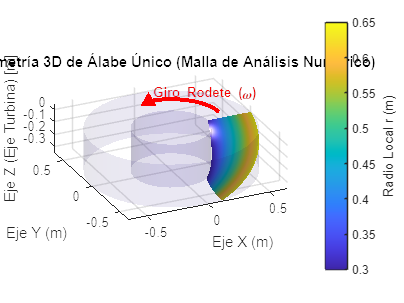


%% ========================================================================
% BLOQUE 6: RENDERIZADO VISUAL EN 3D - FIGURA 1 (ÁLABE ÚNICO DE REFERENCIA)
% =========================================================================
figure('Name', 'Figura 1: Álabe Único de Referencia - Malla de Integración', 'Color', 'w');

surf(X, Y, Z, r_vec .* ones(N_cuerda, 1), 'FaceColor', 'interp', 'EdgeColor', [0.1 0.1 0.1], 'EdgeAlpha', 0.2);
hold on;

% Representación del cubo interior
[X_cubo, Y_cubo, Z_cubo] = cylinder(R_cubo, 40);
Z_cubo = Z_cubo * (-L_z);
mesh(X_cubo, Y_cubo, Z_cubo, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.15, 'EdgeColor', [0.4 0.4 0.4]);

% Representación de la carcasa exterior
[X_punta, Y_punta, Z_punta] = cylinder(R_punta, 40);
Z_punta = Z_punta * (-L_z);
mesh(X_punta, Y_punta, Z_punta, 'FaceColor', [0.3 0.6 0.9], 'FaceAlpha', 0.10, 'EdgeColor', [0.6 0.6 0.6], 'EdgeAlpha', 0.1);

% Indicador vectorial del sentido de rotación (Antihorario)
ang_flecha = linspace(0, pi/2, 20);
r_flecha = R_punta * 0.6;
z_flecha = 0.05;
plot3(r_flecha*cos(ang_flecha), r_flecha*sin(ang_flecha), z_flecha*ones(size(ang_flecha)), 'r-', 'LineWidth', 3);
plot3(0, r_flecha, z_flecha, 'r^', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
text(0.05, r_flecha + 0.05, z_flecha + 0.03, 'Giro Rodete (\omega)', 'Color', 'r', 'FontSize', 10, 'FontWeight', 'bold');

title('Geometría 3D de Álabe Único (Malla de Análisis Numérico)');
xlabel('Eje X (m)'); ylabel('Eje Y (m)'); zlabel('Eje Z (Eje Turbina) [m]');
colormap(parula(256));
h_bar = colorbar; ylabel(h_bar, 'Radio Local r (m)', 'FontSize', 10);
clim([R_cubo, R_punta]);
axis equal; grid on; view(-25, 25);
camlight('headlight'); lighting gouraud; shading interp;

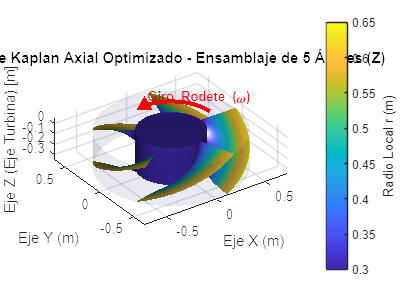


%% ========================================================================
% BLOQUE 7: RENDERIZADO VISUAL EN 3D - FIGURA 2 (RODETE COMPLETO OPTIMIZADO)
% Replicación del álabe patrón mediante matrices de rotación angular
% =========================================================================
figure('Name', sprintf('Figura 2: Rodete Completo Optimizado (%d Álabes)', Z_optimo), 'Color', 'w');
hold on;

% Paso angular entre álabes consecutivos (Delta theta)
delta_angle = (2 * pi) / Z_optimo;

% Matriz de color basada en el radio con dimensiones exactas [N_cuerda x N_radios]
[R_grid, ~] = meshgrid(r_vec, z_vec); 

% Bucle de clonación cromática y angular del álabe geométrico
for k = 1:Z_optimo
    current_angle = (k - 1) * delta_angle;
    
    % Aplicación de la matriz de rotación en el plano XY
    X_rot = X * cos(current_angle) - Y * sin(current_angle);
    Y_rot = X * sin(current_angle) + Y * cos(current_angle);
    Z_rot = Z;
    
    % Dibujar cada álabe posicionado
    surf(X_rot, Y_rot, Z_rot, R_grid, 'FaceColor', 'interp', 'EdgeColor', 'none');
end

% --- RENDERIZADO SÓLIDO DEL CUBO MECÁNICO CENTRAL ---
[X_cubo_sol, Y_cubo_sol, Z_cubo_sol] = cylinder(R_cubo, 60);
Z_cubo_sol = Z_cubo_sol * (-L_z);

% 1. Cilindro lateral del cubo
C_cubo = R_cubo * ones(size(Z_cubo_sol));
surf(X_cubo_sol, Y_cubo_sol, Z_cubo_sol, C_cubo, 'FaceColor', [0.4 0.4 0.4], 'EdgeColor', 'none', 'FaceAlpha', 0.95);

% 2. Tapas del cubo
X_tapa_sup = [zeros(1, 61); X_cubo_sol(1,:)];
Y_tapa_sup = [zeros(1, 61); Y_cubo_sol(1,:)];
Z_tapa_sup = zeros(2, 61);
C_tapa = R_cubo * ones(2, 61);
surf(X_tapa_sup, Y_tapa_sup, Z_tapa_sup, C_tapa, 'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'none');

Z_tapa_inf = -L_z * ones(2, 61);
surf(X_tapa_sup, Y_tapa_sup, Z_tapa_inf, C_tapa, 'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'none');

% --- DIBUJAR CONTORNO EXTERIOR DE LA CARCASA ---
% Representación de la carcasa exterior
[X_punta, Y_punta, Z_punta] = cylinder(R_punta, 40);
Z_punta = Z_punta * (-L_z);
mesh(X_punta, Y_punta, Z_punta, 'FaceColor', [0.3 0.6 0.9], 'FaceAlpha', 0.10, 'EdgeColor', [0.6 0.6 0.6], 'EdgeAlpha', 0.1);

% --- INDICADOR DEL SENTIDO DE GIRO (ANTIHORARIO) ---
plot3(r_flecha*cos(ang_flecha), r_flecha*sin(ang_flecha), z_flecha*ones(size(ang_flecha)), 'r-', 'LineWidth', 3);
plot3(0, r_flecha, z_flecha, 'r^', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
text(0.05, r_flecha + 0.05, z_flecha + 0.03, 'Giro Rodete (\omega)', 'Color', 'r', 'FontSize', 10, 'FontWeight', 'bold');

% --- CONFIGURACIÓN ESTÉTICA DE LA FIGURA ---
title(sprintf('Rodete Kaplan Axial Optimizado - Ensamblaje de %d Álabes (Z)', Z_optimo));
xlabel('Eje X (m)'); ylabel('Eje Y (m)'); zlabel('Eje Z (Eje Turbina) [m]');
colormap(parula(256));
h_bar2 = colorbar; ylabel(h_bar2, 'Radio Local r (m)', 'FontSize', 10);
clim([R_cubo, R_punta]);
axis equal; grid on; view(-35, 30);
camlight('headlight'); lighting gouraud; shading interp;